labels = []


labels =

     []



clf;
hold on;
for w_thickness = 0.025:0.01:0.045
    for esu_thickness = 0.2:0.4:0.8
        [t, Temp] = solar_house_sim(w_thickness, esu_thickness);
        plot(t/3600/24,Temp, 'linewidth', 1.5);
    end
end
label1 = "W_T: 0.025 m, S_T: 0.2m";
label2 = "W_T: 0.025 m, S_T: 0.6m";
label3 = "W_T: 0.035 m, S_T: 0.2m";
label4 = "W_T: 0.035 m, S_T: 0.6m";
label5 = "W_T: 0.045 m, S_T: 0.2m";
label6 = "W_T: 0.045 m, S_T: 0.6m";
legend(label1, label2, label3, label4, label5, label6)
xlim([5 15])
labels


labels =

     []



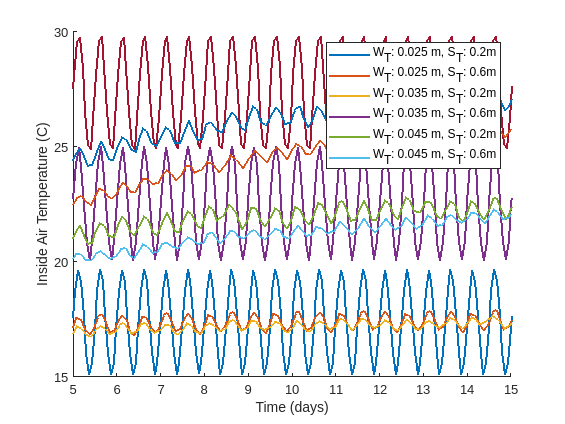

ylim([15 30])
xlabel('Time (days)');
ylabel('Inside Air Temperature (C)');
% legend(labels)
hold off;

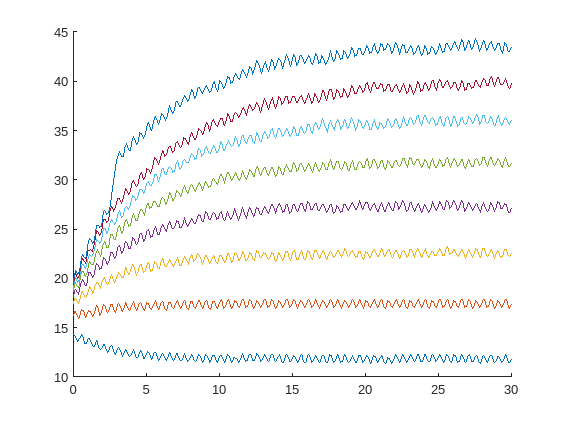

clf; hold on;
esu_thickness = 0.5;
for w_thickness = 0.015:0.01:0.085
    [t, Temp] = solar_house_sim(w_thickness, esu_thickness);
    plot(t/3600/24,Temp);  
end
hold off;

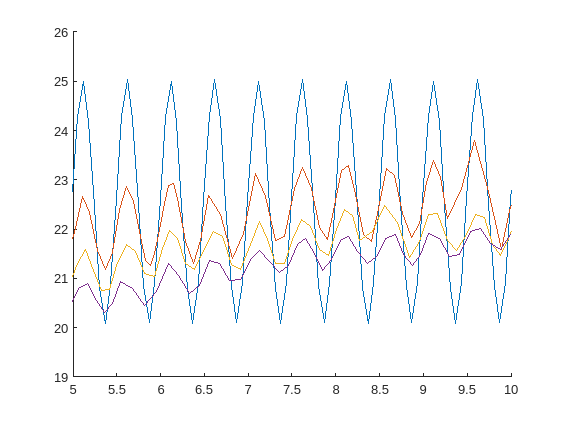

clf; hold on;
w_thickness = 0.035;
for esu_thickness = 0.1:0.2:0.8
    [t, Temp] = solar_house_sim(w_thickness, esu_thickness);
    plot(t/3600/24,Temp,'LineWidth',1.2);  
end
xlim([5 10])
ylim([19 26])